% Frequencia de amostragem
Fs = 8000;
% Grava 10 segundos de som, com 16 bits por amostra e 1 canal (mono)
fala = audiorecorder(Fs,16,1);
disp('Por favor fale durante 10 segundos...');

Por favor fale durante 10 segundos...


recordblocking(fala,10);
disp('...gravação terminada.');

...gravação terminada.


% Reproduz fala para verificação
play(fala);
f = getaudiodata(fala,'int16');
%Grava em ficheiro de áudio
audiowrite('fala2.wav',f,Fs);


# Chapter 1 - How is speech processed in a cell phone conversation?

This is a companion file to the book "Applied Signal Processing", by T.Dutoit and F. Marques, Springer 2008.

It is supposed to be run cell-by-cell, using the cell mode of MATLAB 6 and later versions. Search for "what are cells" in the product help of MATLAB to know how to use them.

This file uses the SIGNAL_PROCESSING toolbox of MATLAB.

In this script, we will see how LPC-based analysis-synthesis lies at the very heart of mobile phone transmission of speech. We will first examine the contents of a speech file, in Section 1. Then we will perform LP analysis and synthesis on a voice and on an unvoiced frame, in Sections 2 and 3 respectively. We will then generalize this approach to the complete speech file, by first synthesizing all frames as voiced and imposing a constant pitch, in Section 4, then by synthesizing all frames as unvoiced in section 5, and finally by using the original pitch and voicing information, in Section 6.

Copyright T. Dutoit, N. Moreau, 2007

set(0,'defaultFigureColor','w')

## 1. Examining a speech file

Let us load file 'speech.wav', listen to it, and plot its samples. This file contains the sentence "Paint the circuits" sampled at 8 kHz, with 16 bits. (This sentence was taken from the Open Speech Repository on the web)

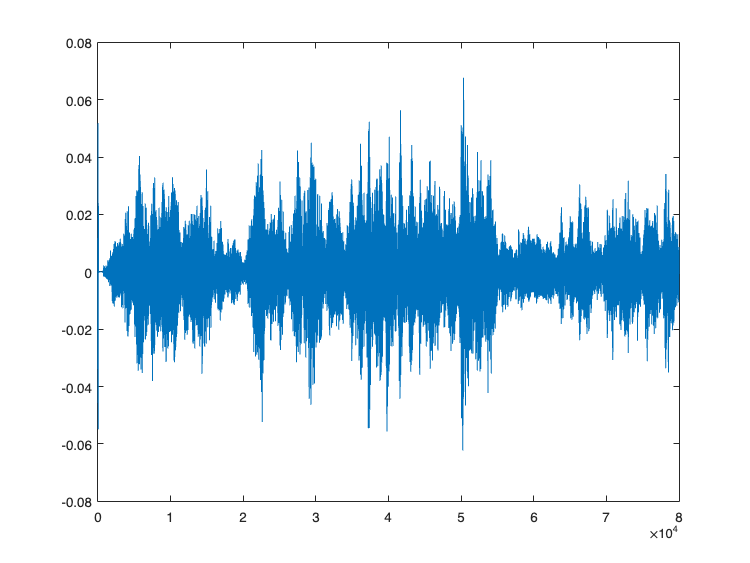

[sound,Fs]=audioread('fala.wav');
%input_signal = (sound(:,1)+sound(:,2))/2;
soundsc(sound,8000);
plot(sound)

The file is about 1.1 s long (9000 samples). One can easily spot the position of the four vowels in this plot, since vowels usually have higher amplitude than other sounds. The vowel 'e' in "the", for instance, is approximately centered on sample 3500.

As such, however, the speech waveform is not "readable", even by an expert phonetician. Its information (phonetic) content is hidden. In order to reveal it to the eyes, let us plot a spectrogram of the signal. For a better graphical result, we choose a wideband spectrogram, by imposing the length of each frame to be approximately 5 ms long (40 samples) and a hamming weighting window.

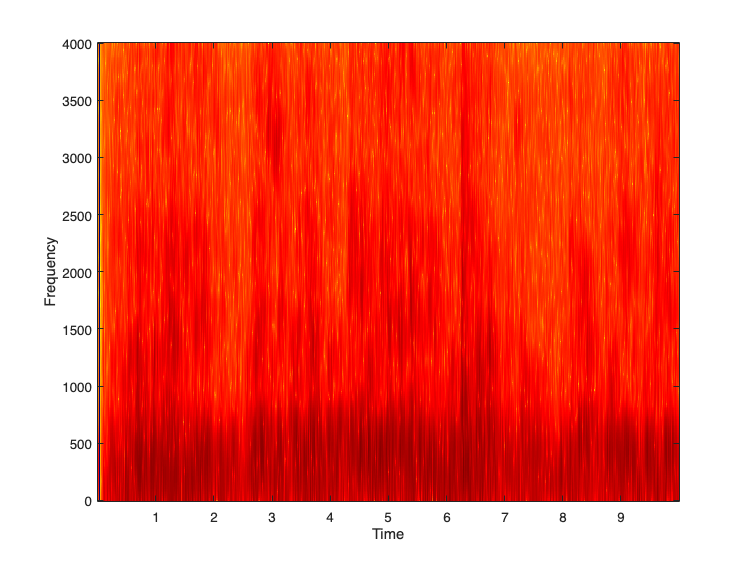

specgram(sound,512,8000,hamming(40))

In this plot, pitch periods appear as vertical lines. As a matter of fact, since the length of analysis frames is very small, some frames fall on the peaks (resp., on the valleys) of pitch periods, and thus appear as a darker (resp., lighter) vertical lines.

In contrast, formants (resonant frequencies of the vocal tract) appear as dark (and rather wide) horizontal traces. Although their frequency is not easy to measure with precision, experts looking at such a spectrogram can actually often read it (i.e. guess the corresponding words). This clearly shows that formants are a good indicator of the underlying speech sounds.

## 2. Linear prediction synthesis of 30 ms of voiced speech

Let us extract a 30 ms frame from a voiced part (i.e. 240 samples) of the speech file, and plot its samples. 

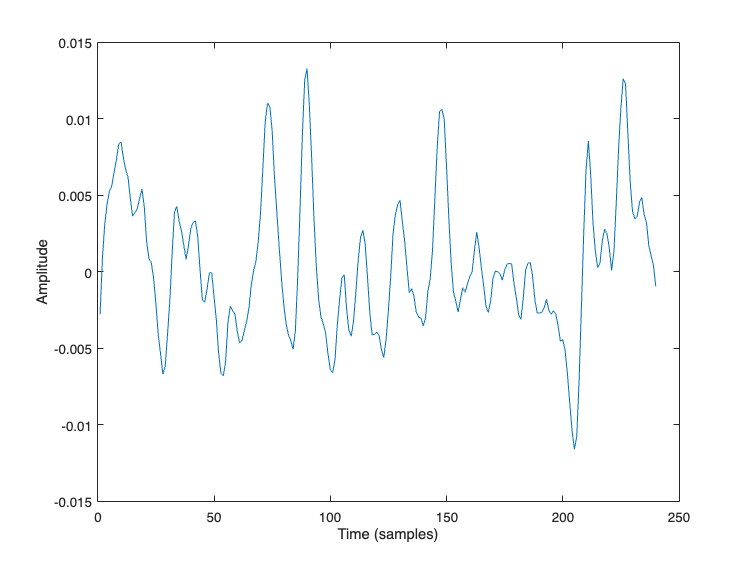

speech=audioread('fala.wav');
input_frame=speech(3500:3739);
plot(input_frame);
xlabel('Time (samples)'); ylabel('Amplitude');

As expected this sound is approximately periodic (period=65 samples, i.e. 80 ms; fundamental frequency = 125 Hz). Notice, though, that this is only apparent; in practice, no sequence of samples can be found more than once in the frame.

Now let us see the spectral content of this speech frame, by plotting its periodogram on 512 points (using a normalized frequency axis; remember pi corresponds to Fs/2, i.e. to 4000 Hz here). 

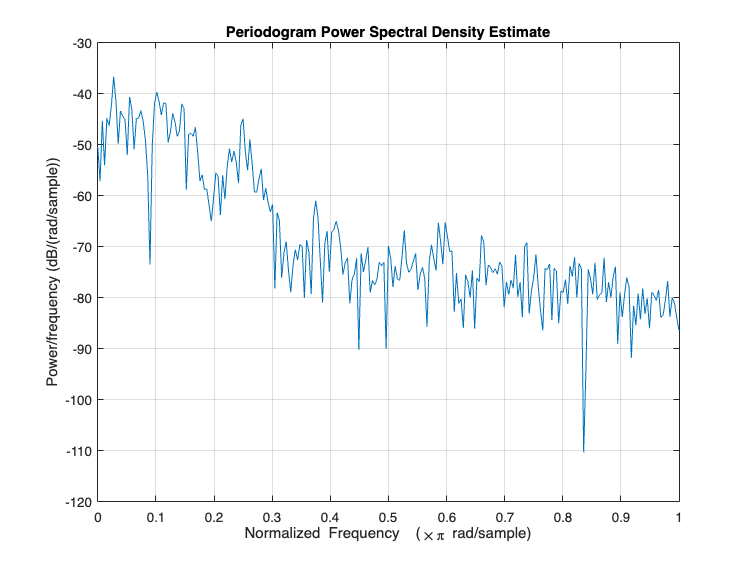

periodogram(input_frame,[],512);

The fundamental frequency appears again at around 125 Hz. One can also roughly estimate the position of formants (peaks in the spectral envelope) at +- 300 Hz, 1400 Hz, 2700 Hz.

Let us now fit an LP model of order 10 to our voiced frame. We obtain the prediction coefficients (ai) and the variance of the residual signal (sigma_square). Notice we do not apply windowing prior to LP analysis now, as it has no tutorial benefit. We will add it in subsequent Sections.

[ai, sigma_square]=lpc(input_frame,10)% mudo pra um 6 não temos muitos coeficientes então não dá pra identificar vogais

ai =     1.0000   -1.8271    1.5123   -0.7711    0.1094    0.1716   -0.3060    0.2201   -0.0006    0.1363   -0.1372


sigma_square = 1.8833e-06

sigma=sqrt(sigma_square);

The estimation algorithm inside LPC is called the Levinson-Durbin algorithm. It chooses the coefficients of an FIR filter A(z) so that when passing the input frame into A(Z), the output, termed as the prediction residual, has minimum energy. It can be shown that this leads to a filter which has anti-resonances wherever the input frame has a formant. For this reason, the A(z) filter is termed as the "inverse" filter. Let us plot its frequency response (on 512 points), and superimpose it to that of the "synthesis" filter 1/A(z).

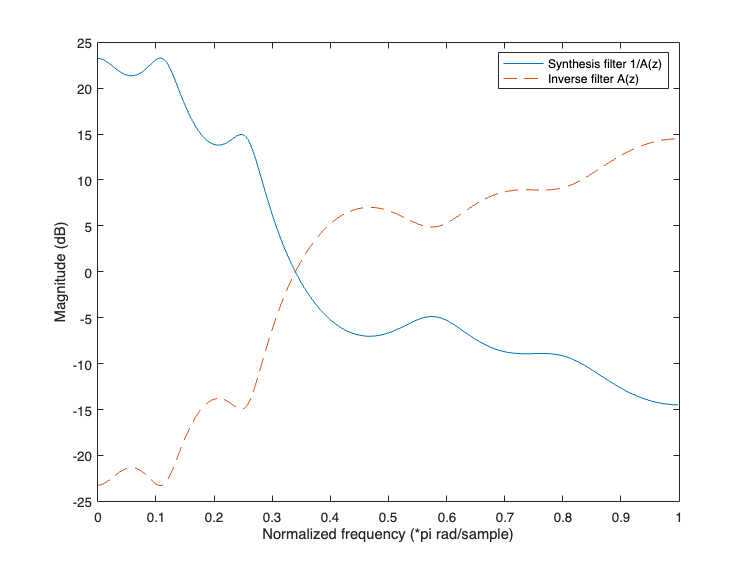

[HI,WI]=freqz(ai,1,512);
[H,W]=freqz(1,ai,512);
plot(W/pi,20*log10(abs(H)),'-',WI/pi,20*log10(abs(HI)),'--');
legend('Synthesis filter 1/A(z)', 'Inverse filter A(z)');
xlabel('Normalized frequency (*pi rad/sample)'); ylabel('Magnitude (dB)');

In other words, the frequency response of the filter 1/A(z) matches the spectral amplitude envelope of the frame. Let us superimpose this frequency response to periodogram of the vowel.

NB: the `periodogram` function of MATLAB actually shows the so-called one-sided periodogram, which has twice the value of the two-sided periodogram in [0,Fs/2]. In order to force MATLAB to show the real value of the two-sided periodogram in [0, Fs/2], we claim Fs=2.

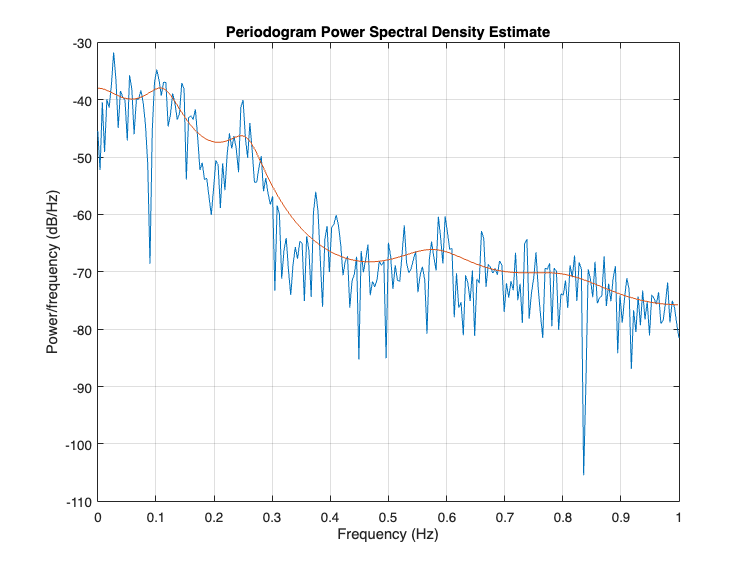

periodogram(input_frame,[],512,2)
hold on;
plot(W/pi,20*log10(sigma*abs(H)));
hold off;

Formants appear again, much better than before. As a matter of fact, LP modelling acts as a parametric spectral estimator, resulting in a smooth estimate.

In other words, the LPC fit has automatically adjusted the poles of the synthesis filter close to the unit circle at angular positions chosen to imitate formant resonances.

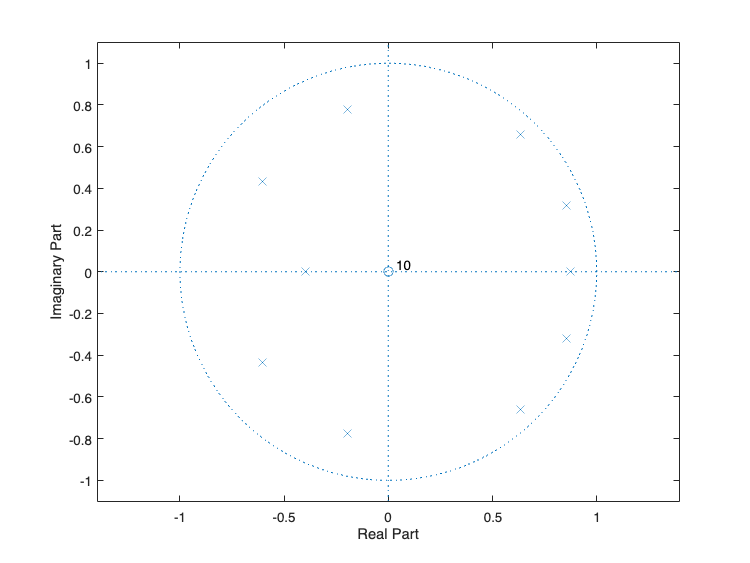

zplane(1,ai);

If we apply the inverse of this filter to the input frame, we obtain the prediction residual.

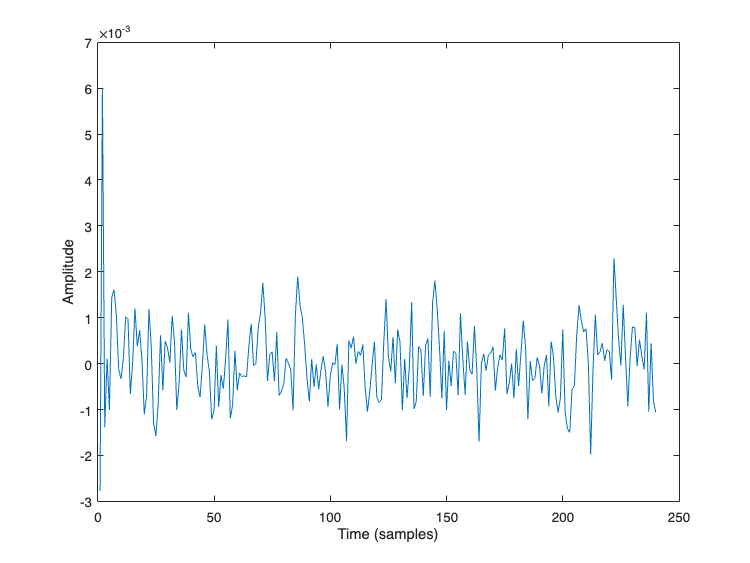

LP_residual=filter(ai,1,input_frame);
plot(LP_residual)
xlabel('Time (samples)'); ylabel('Amplitude');

Let us compare the spectrum of this residual to the original spectrum. The new spectrum is approximately flat; its fine spectral details, however, are the same as those of the analysis frame. In particular, its pitch and harmonics are preserved. 

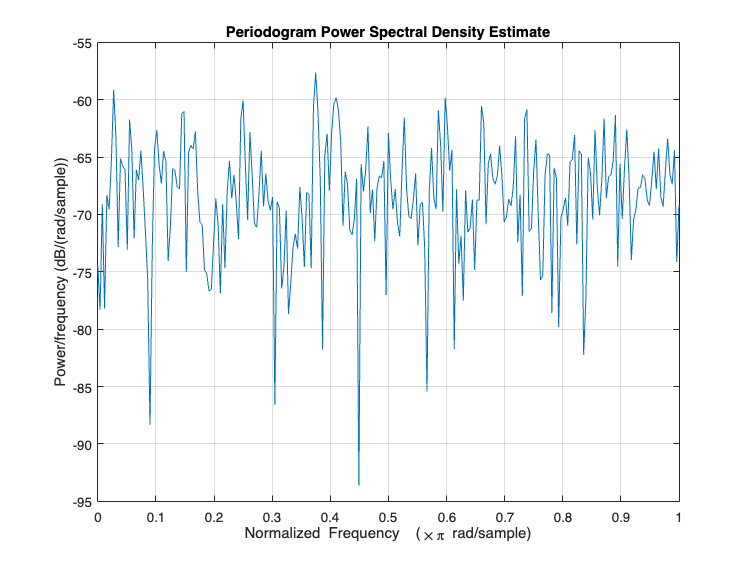

periodogram(LP_residual,[],512);

For obvious reasons, applying the synthesis filter to this prediction residual results in the analysis frame itself (since the synthesis filter is the inverse of the inverse filter).

output_frame=filter(1, ai,LP_residual);
plot(output_frame);
xlabel('Time (samples)'); ylabel('Amplitude');

The LPC model actually models the prediction residual of voiced speech as an impulse train with adjustable pitch period and amplitude. For the speech frame considered, for instance, the LPC excitation is a sequence of pulses separated by 64 zeros (so as to impose a period of 65 samples). Notice we multiply the excitation by some gain so that its variance matches that of the residual signal. 

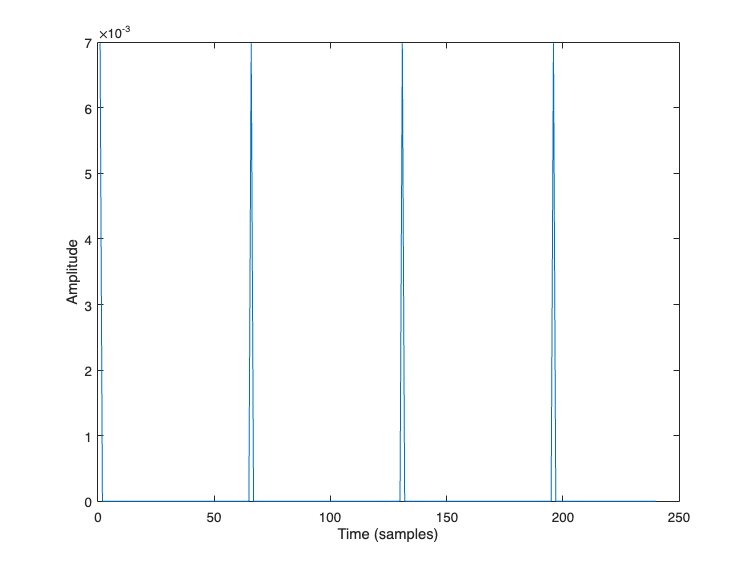

excitation = [1;zeros(64,1);1;zeros(64,1);1;zeros(64,1);1;zeros(44,1)];
gain=sigma/sqrt(1/65);
plot(gain*excitation);
xlabel('Time (samples)'); ylabel('Amplitude');

Clearly, as far as the waveform is concerned, the LPC excitation is far from similar to the prediction residual. Its spectrum, however, has the same broad features as that of the residual: flat envelope, and harmonic content corresponding to F0. The main difference is that the excitation spectrum is "over-harmonic" compared to the residual spectrum.

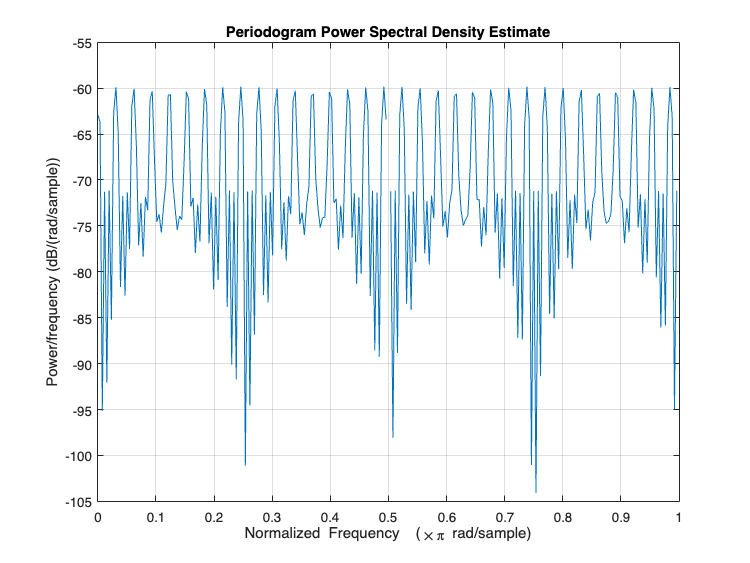

periodogram(gain*excitation,[],512);

Let us now use the synthesis filter to produce an artificial "e". 

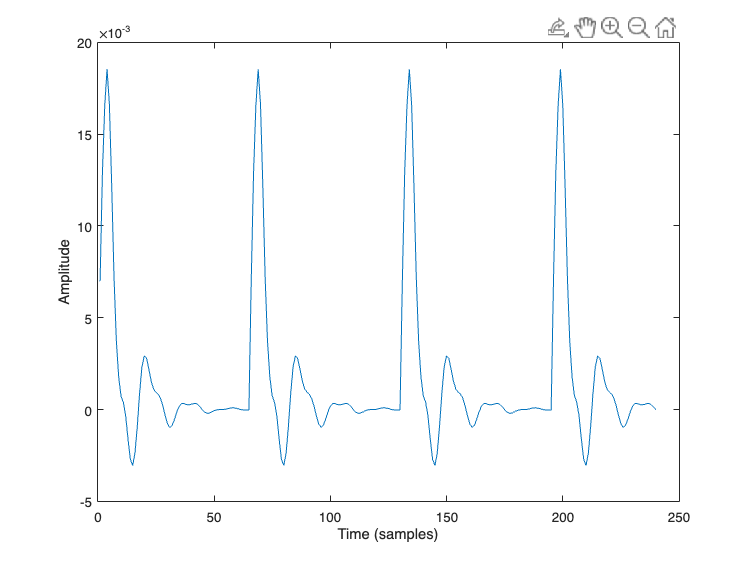

synt_frame=filter(gain,ai,excitation);
plot(synt_frame);
xlabel('Time (samples)'); ylabel('Amplitude');

Although the resulting waveform is obviously different from the original one (this is due to the fact that the LP model does not account for the phase spectrum of the original signal), its spectral envelope is identical. Its fine harmonic details, though, also widely differ (the synthetic frame is actually "over-harmonic" compared to the analysis frame.

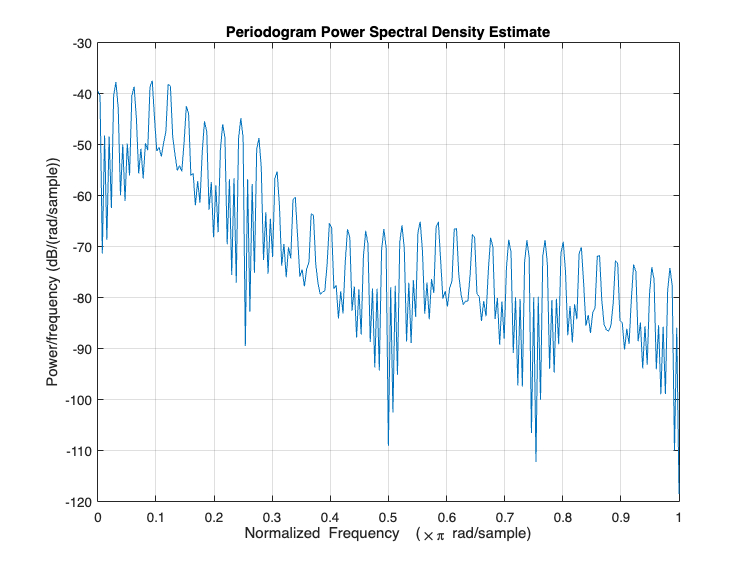

periodogram(synt_frame,[],512);

## 3. Linear prediction synthesis of 30 ms of unvoiced speech

It is easy to apply the same process to an unvoiced frame, and compare the final spectra again. Let us first extract an unvoiced frame and plot it.

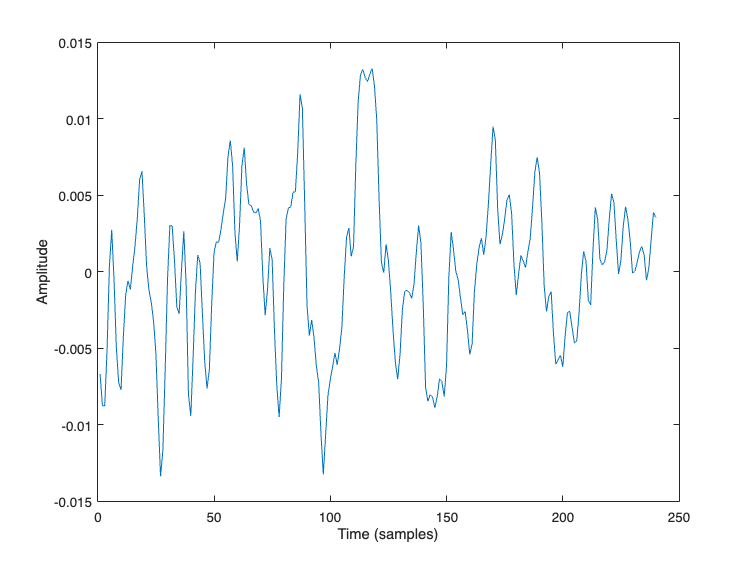

speech=audioread('fala.wav');
input_frame=speech(4500:4739);
plot(input_frame);
xlabel('Time (samples)'); ylabel('Amplitude');

As expected, no clear periodicity appears.

Now let us see the spectral content of this speech frame. Notice that, since we are dealing with noisy signals, we use the averaged periodogram to have a better estimate power spectral densities, although with less frequency resolution than using a simple periodogram. The MATLAB `pwlech` function does this, with 8 sub-frames by default and 50% overlap.

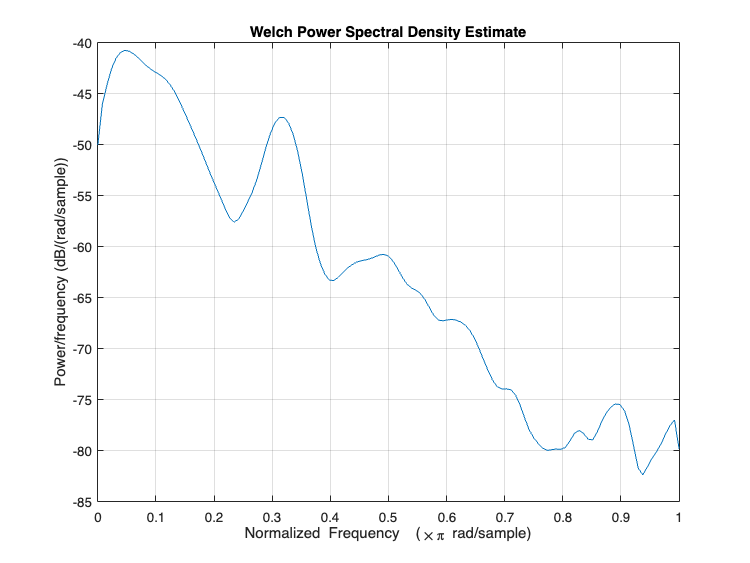

pwelch(input_frame);

Let us now apply an LP model of order 10, and synthesize a new frame. Synthesis is performed by all-pole filtering a Gaussian white noise frame with standard deviation set to the prediction residual standard deviation, sigma.

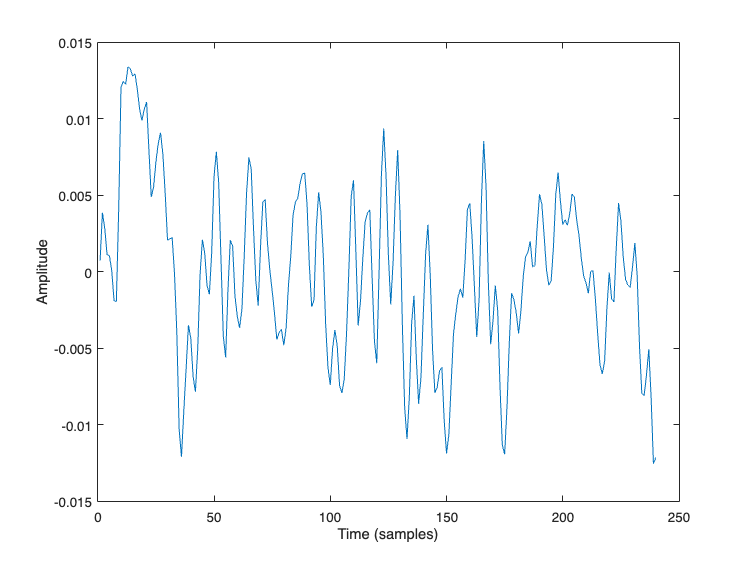

[ai, sigma_square]=lpc(input_frame,10);
sigma=sqrt(sigma_square);
excitation=randn(240,1);
synt_frame=filter(sigma,ai,excitation);
plot(synt_frame);
xlabel('Time (samples)'); ylabel('Amplitude');

The synthetic waveform has no sample in common with the original waveform.

The spectral envelope of this frame, however, is very similar to the original one.

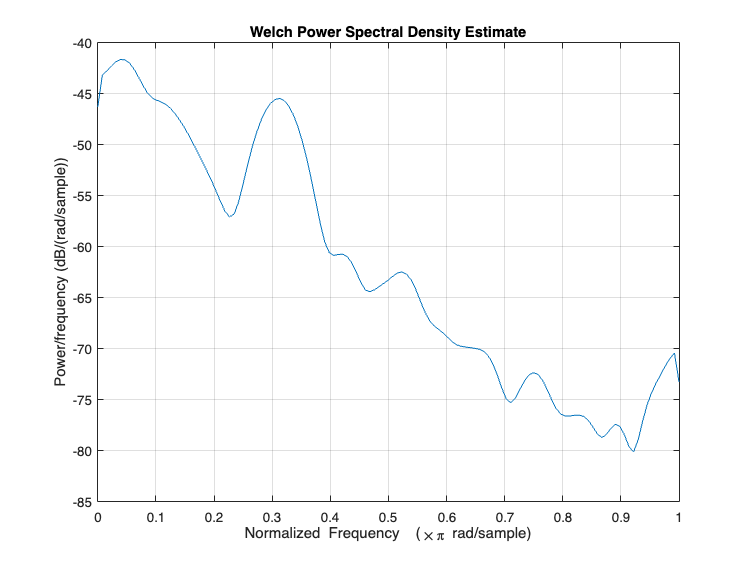

pwelch(synt_frame);

## 4. Linear prediction synthesis of a speech file, with fixed F0

We will now loop the previous operations for the complete speech file, using 30ms analysis frames overlapping by 20 ms. Frames are now weighted by a Hamming window. At synthesis time, we simply synthesize 10 ms of speech, and concatenate the resulting synthetic frames to obtain the output speech file. Let us choose 200 Hz as synthesis F0, for convenience: this way each 10ms excitation frame contains exactly two pulses.

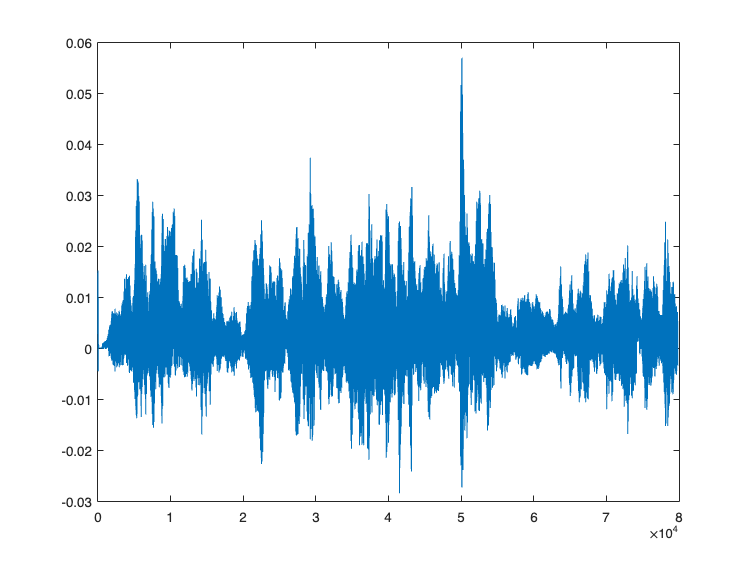

[sound,Fs]=audioread('fala.wav');
%speech = (sound(:,1)+sound(:,2))/2;
synt_speech_V=[]; 

for i=1:(length(sound)-160)/80 % number of frames

    % Extracting the analysis frame
    input_frame=sound((i-1)*80+1:(i-1)*80+240);

    % Hamming window weighting and LPC analysis
    [ai, sigma_square]=lpc(input_frame.*hamming(240),10);
    sigma=sqrt(sigma_square);
    
    % Generating 10 ms of excitation
    % = 2 pitch periods at 200 Hz
    excitation=[1;zeros(39,1);1;zeros(39,1)]; 
    gain=sigma/sqrt(1/40);
    
    % Applying the synthesis filter
    synt_frame=filter(gain, ai,excitation);
    
        % Concatenating synthesis frames    
    synt_speech_V=[synt_speech_V;synt_frame];

end

plot(synt_speech_V);

The output waveform basically contains a sequence of LP filter impulse responses. Let us zoom on 30 ms of LPC speech.

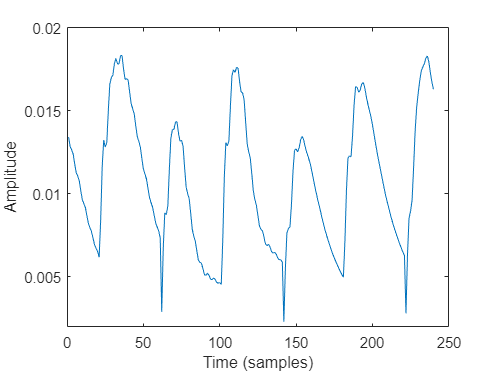

plot(synt_speech_V(3300:3539));
xlabel('Time (samples)'); ylabel('Amplitude');

It appears that in many cases they impulse responses have been cropped. As a matter of fact, since each synthesis frame was composed of two identical impulses, one should expect our LPC speech to exhibit pairs of identical pitch periods. This is not the case, due to the fact that for producing each new synthetic frame the internal variables of the synthesis filter are implicitly reset to zero. We can avoid this problem by maintaining the internal variables of the filter from the end of each frame to the beginning of the next one.

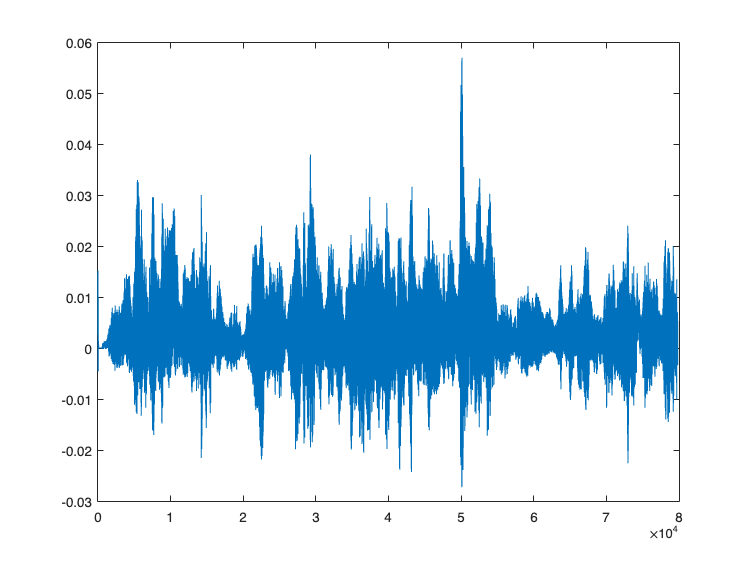

[sound,Fs]=audioread('fala.wav');
%speech = (sound(:,1)+sound(:,2))/2;
synt_speech_V=[]; 

z=zeros(10,1); % internal variables of the synthesis filter

for i=1:(length(sound)-160)/80;
    
    input_frame=sound((i-1)*80+1:(i-1)*80+240);
    [ai, sigma_square]=lpc(input_frame.*hamming(240),10);
    sigma=sqrt(sigma_square);
    
    % Generating 10 ms of excitation
    excitation=[1;zeros(39,1);1;zeros(39,1)]; 
    gain=sigma/sqrt(1/40);
    
    % Applying the synthesis filter
    % Taking care of the internal variables of the filter
    [synt_frame,z]=filter(gain, ai, excitation, z);
    
    synt_speech_V=[synt_speech_V;synt_frame];

end

plot(synt_speech_V);

soundsc(synt_speech_V,8000);

This time the end of each impulse response is properly added to the beginning of the next one, which results in more smoothly evolving periods.

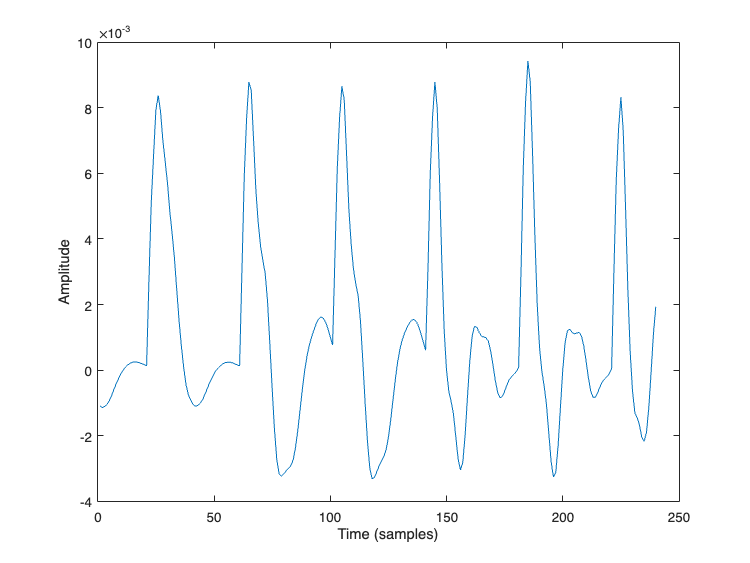

plot(synt_speech_V(3300:3539));
xlabel('Time (samples)'); ylabel('Amplitude');

If we want to synthesize speech with constant pitch period length different from a sub-multiple of 80 samples (say, 70 samples), we additionally need to take care of a possible pitch period offset in the excitation signal.

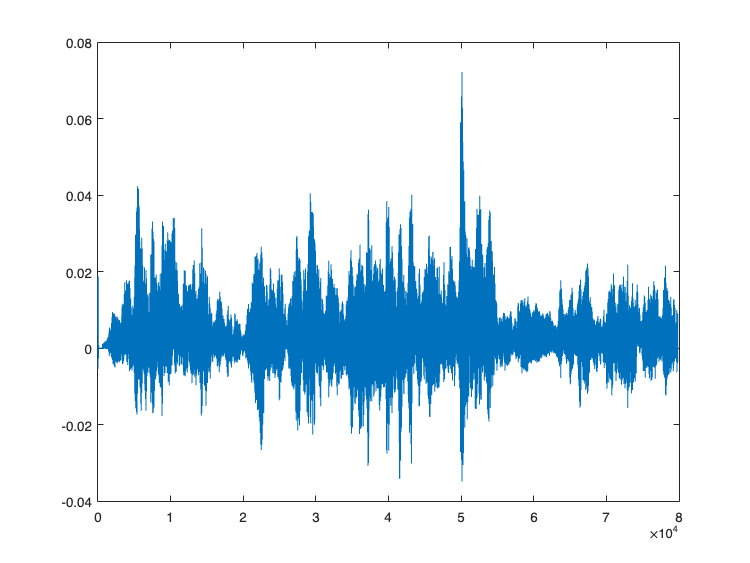

[sound,Fs]=audioread('fala.wav');
%speech = (sound(:,1)+sound(:,2))/2;
synt_speech_V=[]; 
z=zeros(10,1); 

offset=0; % Offset of the next pitch pulse with respect 
             %      to the start of the current frame
N0=65;   % Constant synthesis pitch period (in samples)

for i=1:(length(sound)-160)/80;

    input_frame=sound((i-1)*80+1:(i-1)*80+240);
    [ai, sigma_square]=lpc(input_frame.*hamming(240),10);
    sigma=sqrt(sigma_square);
    
    % Generating 10 ms of excitation
    % taking a possible offset into account
    
    % if pitch period length > excitation frame length
    if offset>=80  
        excitation=zeros(80,1);
        offset=offset-80;
    else 
        % complete the previously unfinished pitch period
        excitation=zeros(offset,1); 
        % for all pitch periods in the remaining of the frame
        for j=1:floor((80-offset)/N0) 
            % add one excitation period
            excitation=[excitation;1;zeros(N0-1,1)]; 
        end;
        % number of samples left in the excitation frame
        flush=80-length(excitation); 
        if flush~=0 
            % fill the frame with a partial pitch period
            excitation=[excitation;1;zeros(flush-1,1)]; 
            % remember to fill the remaining of the period in next frame 
            offset=N0-flush; 
        else offset=0;
        end
    end
    gain=sigma/sqrt(1/N0);
       
    [synt_frame,z]=filter(gain, ai, excitation, z);
    synt_speech_V=[synt_speech_V;synt_frame];

end

plot(synt_speech_V);

soundsc(synt_speech_V,8000);

## 5. Unvoiced linear prediction synthesis of a speech file

Synthesizing the complete speech file as LPC unvoiced speech is easy.

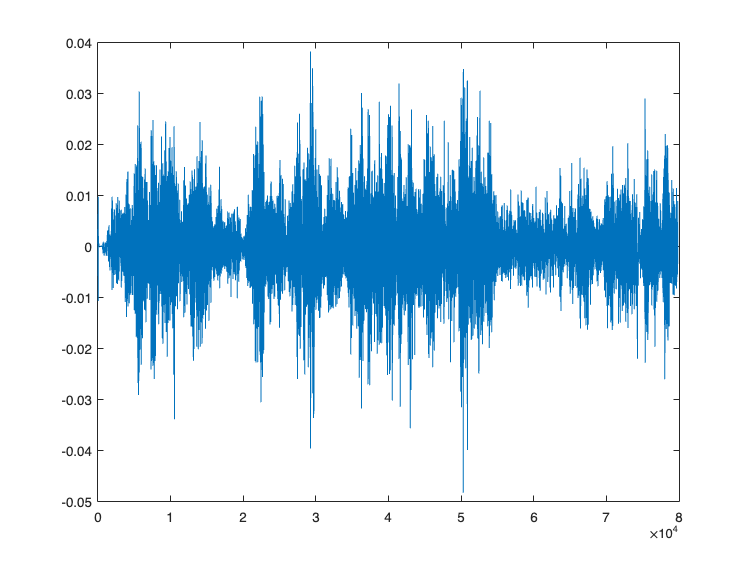

[speech,Fs]=audioread('fala.wav');
%speech = (sound(:,1)+sound(:,2))/2;
synt_speech_UV=[]; 
z=zeros(10,1); 

for i=1:(length(speech)-160)/80;
    
    input_frame=speech((i-1)*80+1:(i-1)*80+240);
    [ai, sigma_square]=lpc(input_frame.*hamming(240),10);
    sigma=sqrt(sigma_square);

    % Generating 10 ms of excitation
    excitation=randn(80,1); % White Gaussian noise
    gain=sigma;
    
    [synt_frame,z]=filter(gain, ai, excitation, z);
    synt_speech_UV=[synt_speech_UV;synt_frame];

end

plot(synt_speech_UV);

%sound(synt_speech_UV,8000);

## 6. Linear prediction synthesis of a speech file, with original F0

We will now synthesize the same speech, using the original F0. We will thus have to deal with the additional problems of pitch estimation (on a frame-by-frame basis), including voiced/unvoiced decision. This approach is similar to the LPC10 that of the coder (except we do not quantize coefficients here).

**MATLAB function involved:**

- `T0=pitch(speech_frame)` : returns the pitch period T0 (in samples) of a speech frame (T0 is set to zero when the frame is detected as unvoiced). T0 is obtained from the maximum of the (estimated) autocorrelation of the LPC residual. Voiced/unvoiced decision is based on the ratio of this maximum by the variance of the residual. This simple algorithm is not optimal, but will do the job for this proof of concept.

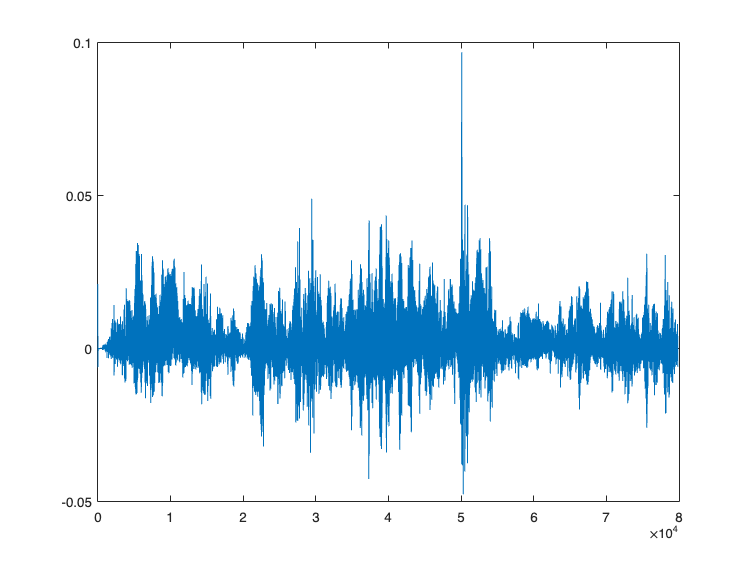

[speech,Fs]=audioread('fala.wav');
%speech = (sound(:,1)+sound(:,2))/2;
synt_speech_LPC10=[]; 
z=zeros(10,1); 
offset=0; 

for i=1:(length(speech)-160)/80;
    
    input_frame=speech((i-1)*80+1:(i-1)*80+240);
    [ai, sigma_square]=lpc(input_frame.*hamming(240),10);
    sigma=sqrt(sigma_square);
    
    % local synthesis pitch period (in samples)
    N0=pitch(input_frame); 
    
    % Generating 10 ms of excitation
    if N0~=0 % voiced frame
        % Generate 10 ms of voiced excitation
        % taking a possible offset into account
        if offset>=80  
            excitation=zeros(80,1);
            offset=offset-80;
        else 
            excitation=zeros(offset,1); 
            for j=1:floor((80-offset)/N0) 
                excitation=[excitation;1;zeros(N0-1,1)]; 
            end;
            flush=80-length(excitation); 
            if flush~=0 
                excitation=[excitation;1;zeros(flush-1,1)]; 
                offset=N0-flush; 
            else offset=0;
            end
        end 
        gain=sigma/sqrt(1/N0);
    else
        % Generate 10 ms of unvoiced voiced excitation
        excitation=randn(80,1); % White Gaussian noise
        gain=sigma;
        offset=0; % reset for subsequent voiced frames
    end;        
    
    [synt_frame, z]=filter(gain, ai,excitation, z);
    synt_speech_LPC10=[synt_speech_LPC10;synt_frame];

end

plot(synt_speech_LPC10);

soundsc(synt_speech_LPC10,8000);

The resulting synthetic speech is intelligible. It shows the same formants as the original speech. It is therefore acoustically similar to the original, except for the additional buzzyness which has been added by the LP model.

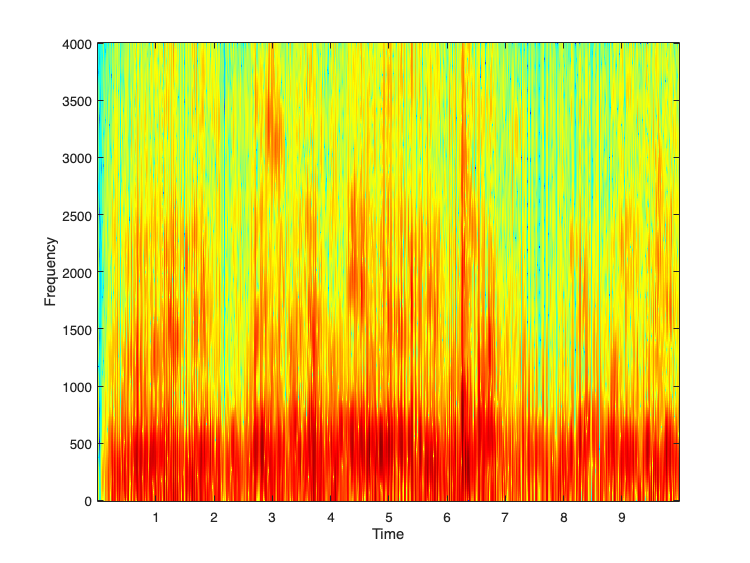

specgram(synt_speech_LPC10,512,8000,hamming(40))

It is easy to estimate the total bit-rate corresponding to this proof-of-concept: 42 bits are required for inaudible quantization of the prediction coefficients. Adding 7 bits for pitch and V/UV and 5 bits for gain gives 54 bits every 10ms: 5400 bits/s. LPC10 was normalized at 2400 bits/s, which was achieved by using larger synthesis frames (22.5 ms).